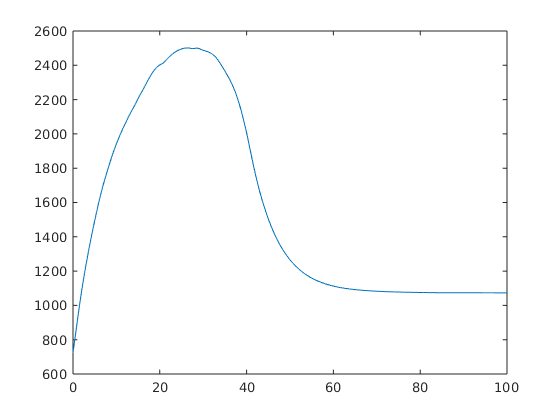

basePath = "~/Dropbox/xps/eQ/build/";

% LOAD FILE
% [file path] = uigetfile('~/Dropbox/xps/eQ/build/*.json', 'Open File');
[file path] = uigetfile(sprintf("%s*.txt", basePath), 'Open File');

thisData = import_eQ_xSliceData(fullfile(path, file), [1, Inf]);
plot(thisData(:, 2), thisData(:,1));


% X0=1.2*thisData(end,2)/2;
X0=1.*thisData(end,2)/2;
dtx=5;
xdata = thisData(:,2);
hdata = thisData(:,1);
endValue = mean(hdata(end-dtx:end));

x0 = find(xdata > X0, 1);
xd = xdata(x0:end);
hd = hdata(x0:end)-endValue;
hdn = hd/hd(1);
h0 = hdn(1);
for i=1:5
    %tau(i) is an index; convert to spatial units below
    tau(i) = find(hdn < h0*exp(-i), 1);    
%     tau(i) = find(hdn < h0*exp(-1), 1);    
%     h0=hdn(tau(i));    
end

figure;
% PLOT THE ORIGINAL DATA (NORMALIZED TO 0,1)
plot(xd,hdn, 'LineWidth', 5);
hold on;
plot(xd(tau), hdn(tau), 'rs');

ltau(1) = xd(tau(1)) - xd(1);
for i=2:length(tau)
    ltau(i) = xd(tau(i)) - xd(tau(i-1));
end
ltau

ltau =     6.3000    6.5000    7.1000    7.0000    5.2000


mlt=mean(ltau)

mlt = 6.4200

std(ltau)

ans = 0.7596

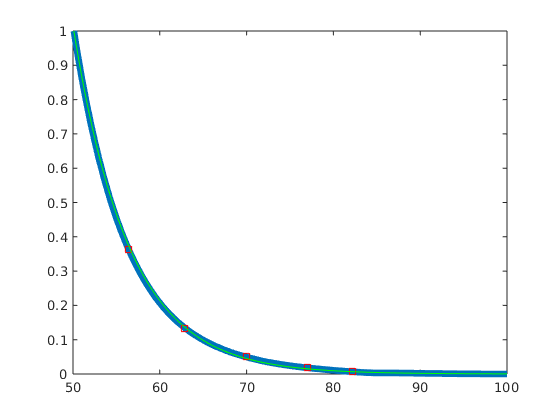


exx=xd-xd(1);
exh=exp(-exx/mlt);
plot(xd, exh, 'g-');
hold off;

return;


% SAVE THE SLICE DATA ITERATIVELY HERE (INCREMENT INDEX)
i=2;
zs(i).name = "50x500um";
zs(i).xd=xd;
zs(i).hd=hd;
save('~/Dropbox/xps/eQ/matlab/sendRecvData/srData.mat', 'zs')


load Dropbox/xps/eQ/matlab/sendRecvData/srData.mat
h1=zs(1).hd/zs(1).hd(1);
h2=zs(2).hd/zs(2).hd(1);
plot(zs(1).xd, [h1 h2]);
legend(zs.name);
